rule = [0  0  0  1  1  1  1  0]

rule =      0     0     0     1     1     1     1     0


function out_bit = apply_rule(in_vec3, rule)
    % three bits correspond the colors, will produce an output bit based on
    % the rule
    % ⬜ -> 0, ⬛ -> 1

    % ⬛⬛⬛
    if in_vec3(1) && in_vec3(2) && in_vec3(3)
        out_bit = rule(1);
    
    % ⬛⬛⬜
    elseif in_vec3(1) && in_vec3(2) && ~in_vec3(3)
        out_bit = rule(2);

    % ⬛⬜⬛
    elseif in_vec3(1) && ~in_vec3(2) && in_vec3(3)
        out_bit = rule(3);

    % ⬛⬜⬜
    elseif in_vec3(1) && ~in_vec3(2) && ~in_vec3(3)
        out_bit = rule(4);

    % ⬜⬛⬛
    elseif ~in_vec3(1) && in_vec3(2) && in_vec3(3)
        out_bit = rule(5);

    % ⬜⬛⬜
    elseif ~in_vec3(1) && in_vec3(2) && ~in_vec3(3)
        out_bit = rule(6);
    
    % ⬜⬜⬛
    elseif ~in_vec3(1) && ~in_vec3(2) && in_vec3(3)
        out_bit = rule(7);

    % ⬜⬜⬜
    else
        out_bit = rule(8);
    end
end
s_1 = apply_rule(s_0, rule)

s_1 = 1

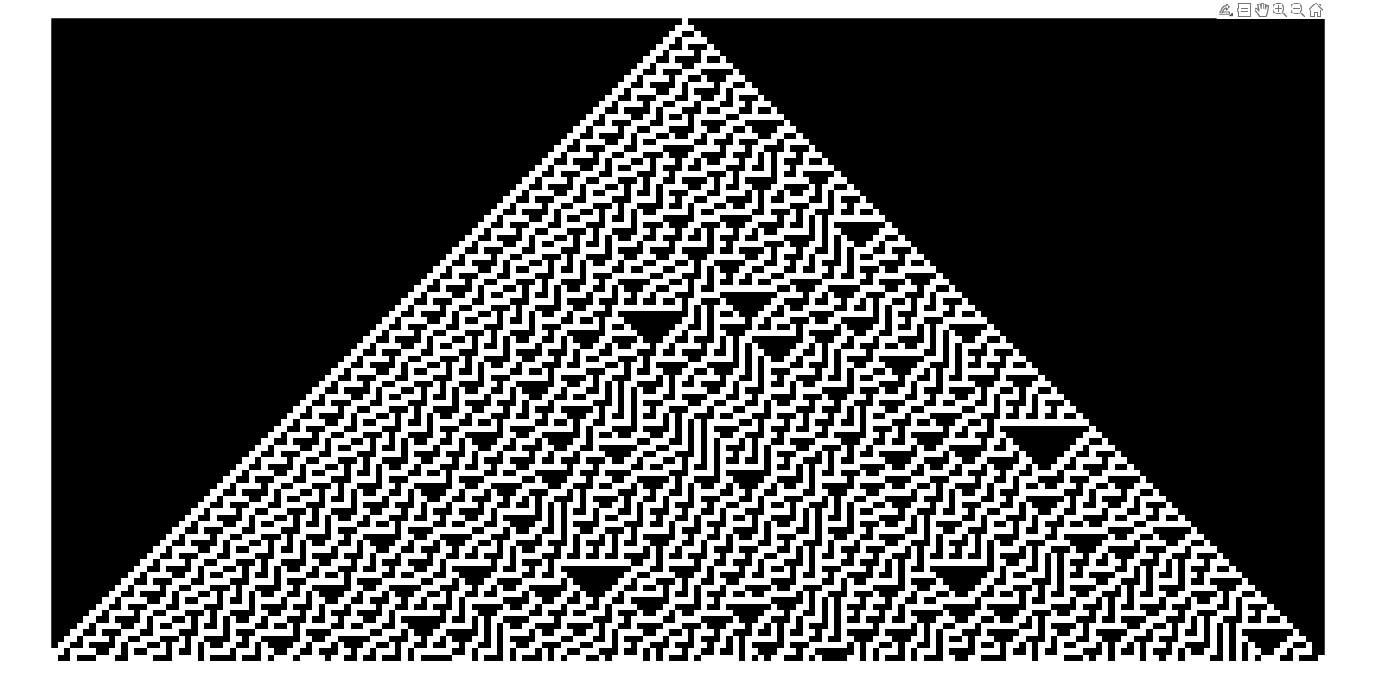

function s_1 = next_eca_state(s_0, rule)
    n = length(s_0);
    s_1 = zeros(1, n);
    s_1(1) = apply_rule([s_0(end) s_0(1:2)], rule); % wrap around start
    for i=1:n-3
        vec3 = s_0(i:i+2);
        s_1(i+1) = apply_rule(vec3, rule);
    end
    s_1(end) = apply_rule([s_0(end-1:end) s_0(1)], rule); % wrap around end
end

iterations = 100;
width = 200;
eca = zeros(iterations, width);
% set middle to 1
eca(1, width/2) = 1; 
for i=1:iterations
    eca(i+1, :) = next_eca_state(eca(i, :), rule);
end
imshow(eca, "InitialMagnification", 2000)